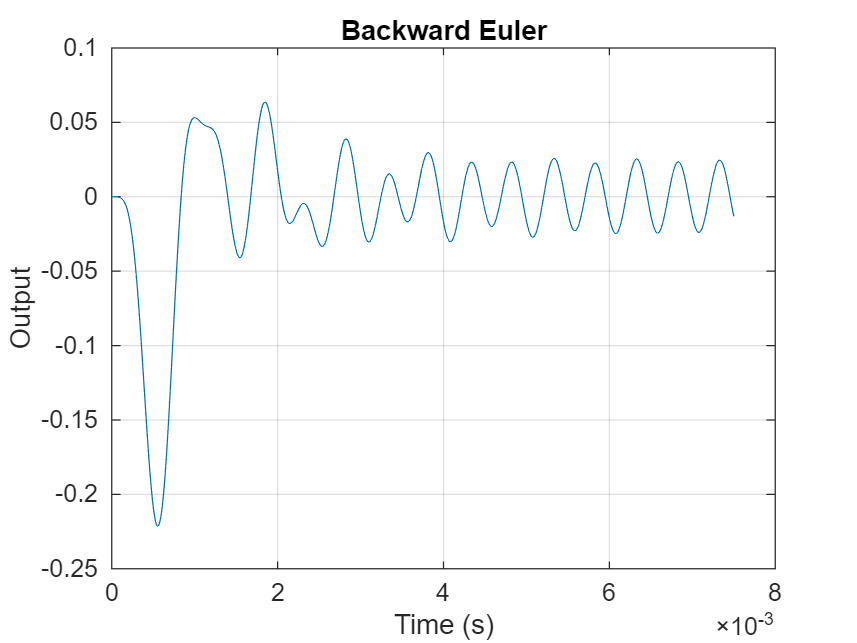

clc
clear
addpath('A1')
CR2 %find G, C, b
t1 = 0;
t2 = 7.5e-3;
h = 5e-6;
in = 'sin(2*pi*2000*t)';
out = 10;
[tpoints, r] = beuler(t1, t2, h, in, out);

figure
plot(tpoints, r)
xlabel('Time (s)')
ylabel('Output')
title('Backward Euler')
grid on

using method from A1

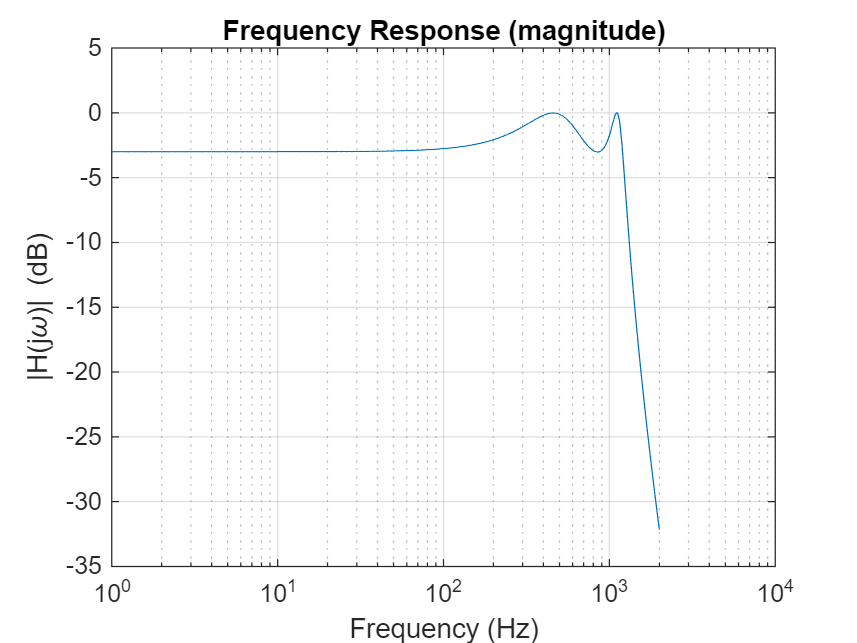

% Vout = node 10
fL = 1;
fH = 2000;
N = 1000;
[f, H] = fsolve(fL, fH, N, out);
mag_dB = 20*log10(abs(H));
phase_deg = unwrap(angle(H))*180/pi -90;

figure;
semilogx(f, mag_dB);
grid on;
xlabel('Frequency (Hz)');
ylabel('|H(j\omega)| (dB)');
title('Frequency Response (magnitude)');

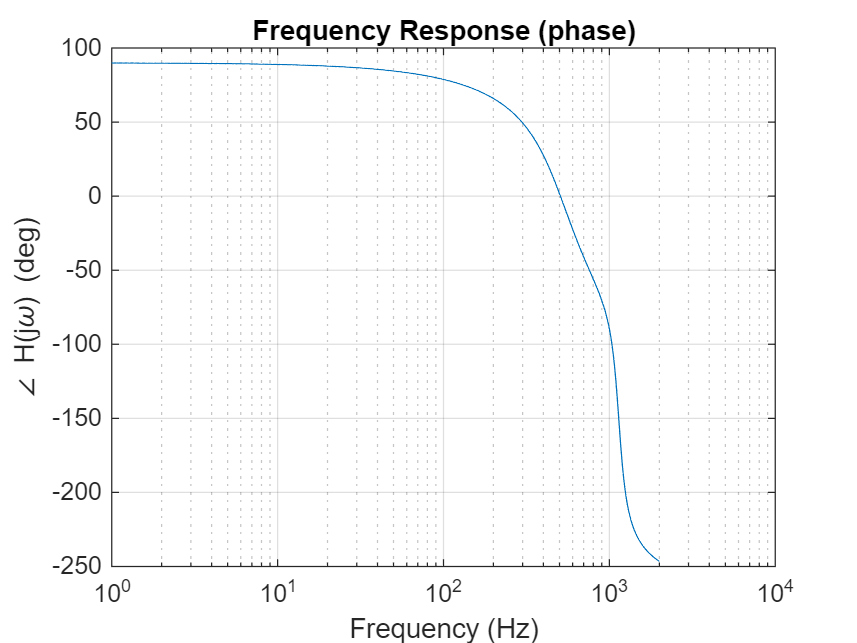


figure;
semilogx(f, phase_deg);
grid on;
xlabel('Frequency (Hz)');
ylabel('\angle H(j\omega) (deg)');
title('Frequency Response (phase)');

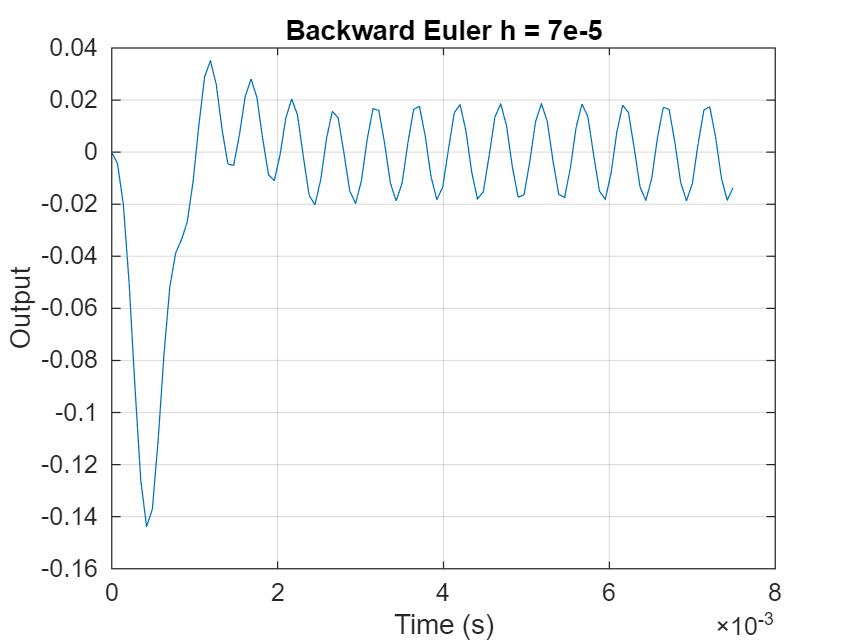

h2 = 7e-5;
h3= 5e-5;
[tpoints_Q16, r_Q16] = beuler(t1, t2, h2, in, out);
[tpoints_Q162, r_Q162] = beuler(t1, t2, h3, in, out);

figure
plot(tpoints_Q16, r_Q16)
xlabel('Time (s)')
ylabel('Output')
title('Backward Euler h = 7e-5')
grid on

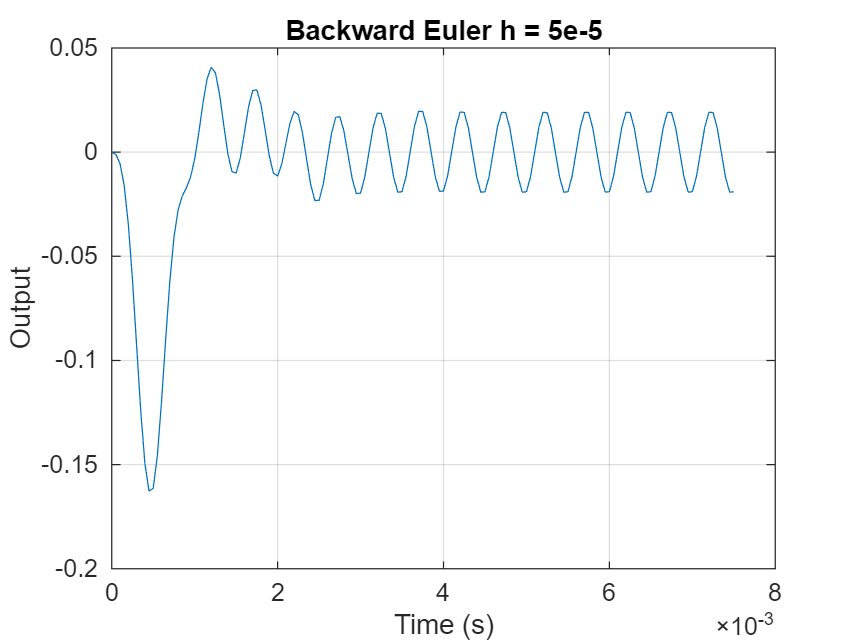


figure
plot(tpoints_Q162, r_Q162)
xlabel('Time (s)')
ylabel('Output')
title('Backward Euler h = 5e-5')
grid on

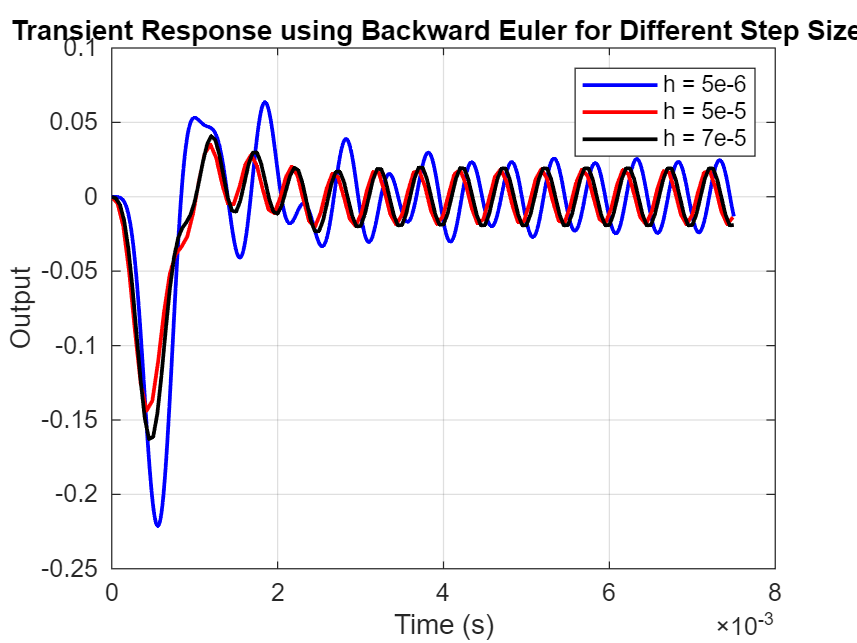


figure
plot(tpoints, r,'b','LineWidth',1.5)
hold on
plot(tpoints_Q16, r_Q16,'r','LineWidth',1.5)
plot(tpoints_Q162, r_Q162,'k','LineWidth',1.5)

xlabel('Time (s)')
ylabel('Output')
title('Transient Response using Backward Euler for Different Step Sizes')
legend('h = 5e-6','h = 5e-5','h = 7e-5')
grid on

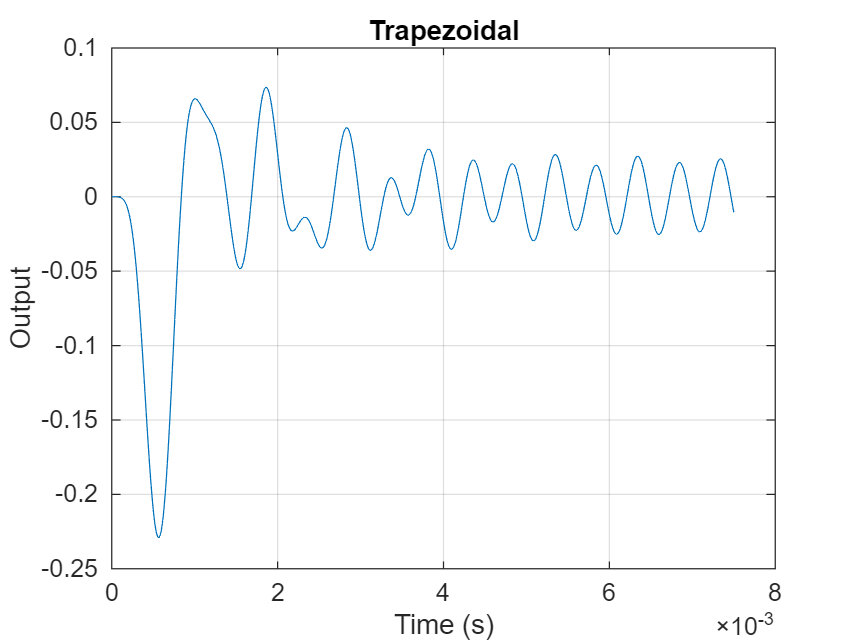

[tpoints_trap, r_trap] = trapezoidal(t1, t2, h, in, out);
figure
plot(tpoints_trap, r_trap)
xlabel('Time (s)')
ylabel('Output')
title('Trapezoidal')
grid on

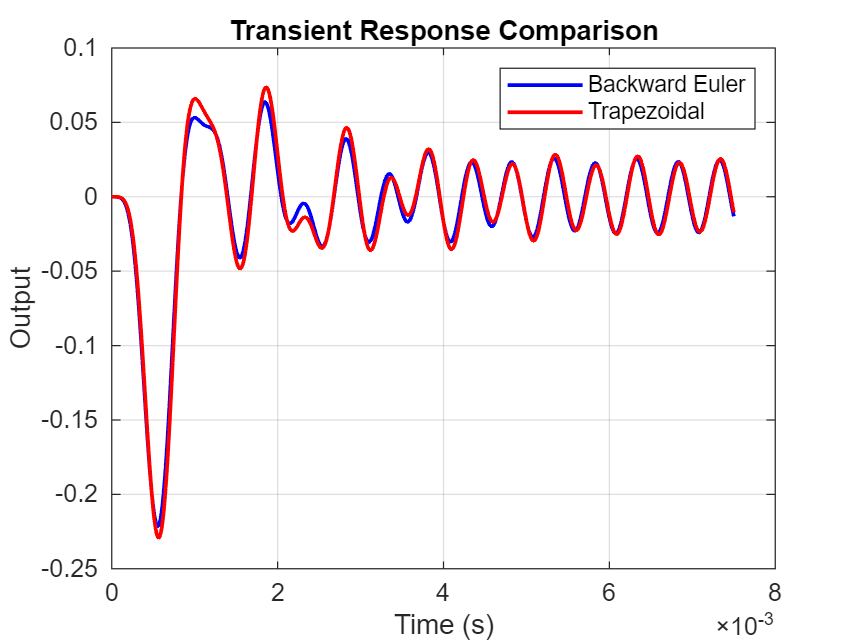


figure
plot(tpoints, r,'b','LineWidth',1.5)
hold on
plot(tpoints_trap, r_trap,'r','LineWidth',1.5)

xlabel('Time (s)')
ylabel('Output')
title('Transient Response Comparison')
legend('Backward Euler','Trapezoidal')
grid on

### **Section 2**

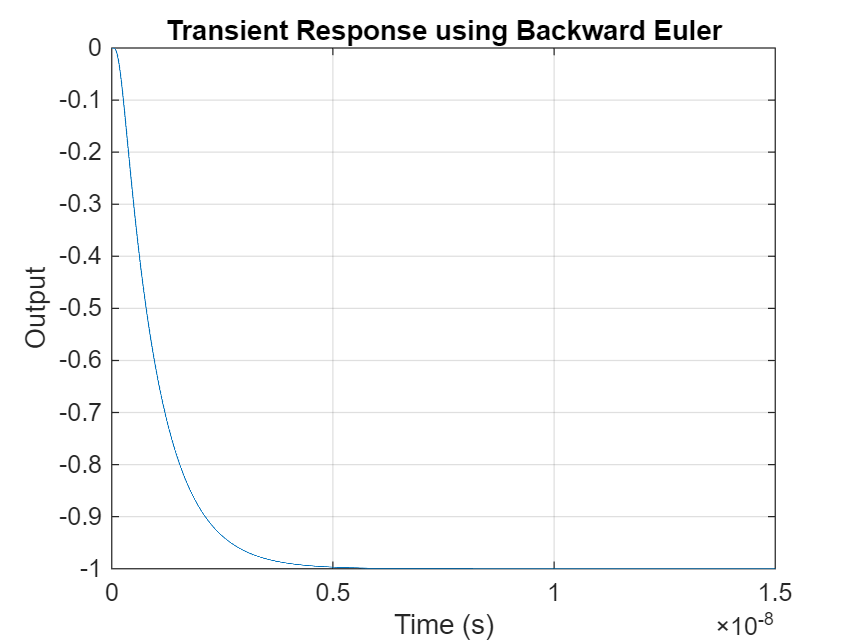

clear
clc
circuit2
t1 = 0;
t2 = 15e-9;
h = 1e-12;
in = 'min(t/(50e-12),1)';
out = 4;

[tpoints, r] = beuler(t1, t2, h, in, out);
figure
plot(tpoints, r)
xlabel('Time (s)')
ylabel('Output')
title('Transient Response using Backward Euler')
grid on

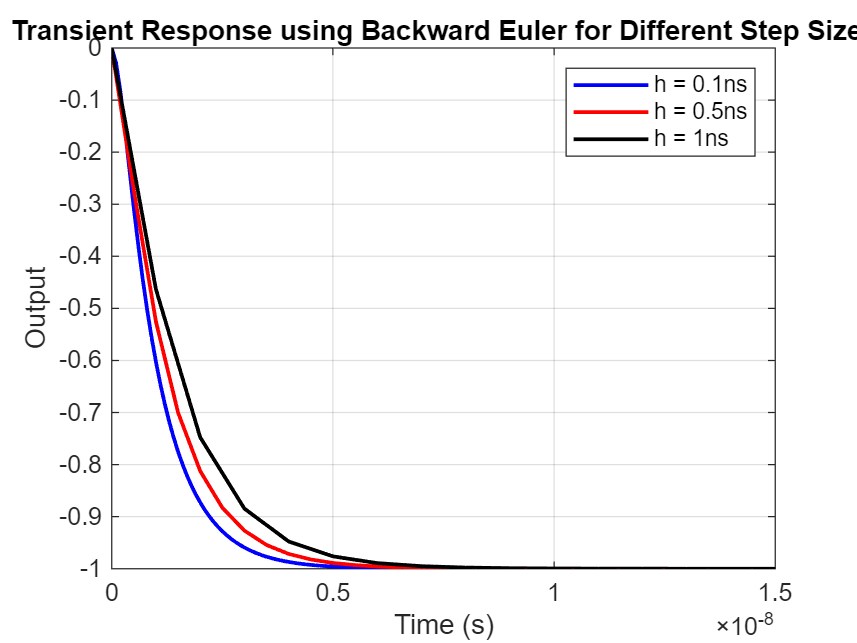


h2 = 0.1e-9;
h3 = 0.5e-9;
h4 = 1e-9;
[tpoints2, r2] = beuler(t1, t2, h2, in, out);
[tpoints3, r3] = beuler(t1, t2, h3, in, out);
[tpoints4, r4] = beuler(t1, t2, h4, in, out);


figure
plot(tpoints2, r2,'b','LineWidth',1.5)
hold on
plot(tpoints3, r3,'r','LineWidth',1.5)
plot(tpoints4, r4,'k','LineWidth',1.5)

xlabel('Time (s)')
ylabel('Output')
title('Transient Response using Backward Euler for Different Step Sizes')
legend('h = 0.1ns','h = 0.5ns','h = 1ns')
grid on

Trapezoidal 

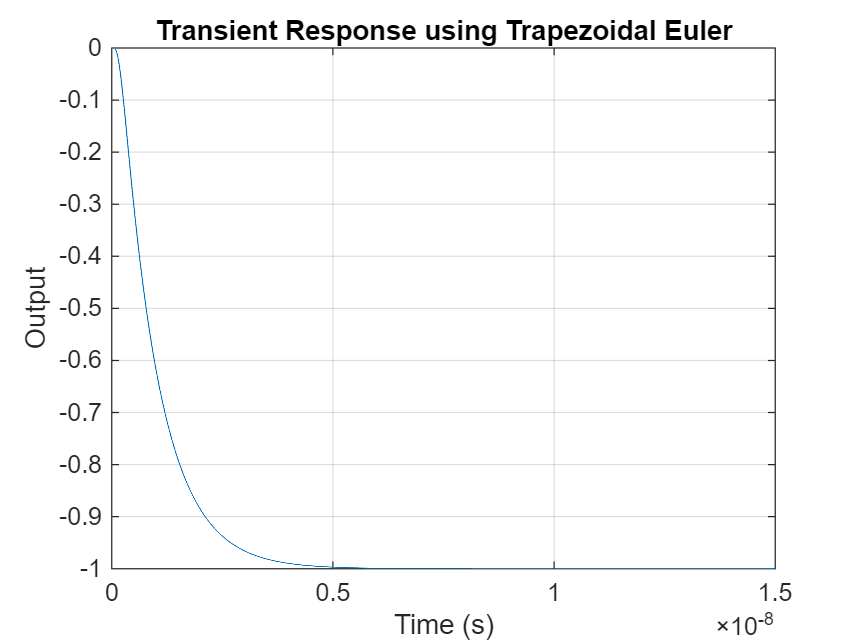

[tpoints_trap, r_trap] = trapezoidal(t1, t2, h, in, out);
figure
plot(tpoints_trap, r_trap)
xlabel('Time (s)')
ylabel('Output')
title('Transient Response using Trapezoidal Euler')
grid on

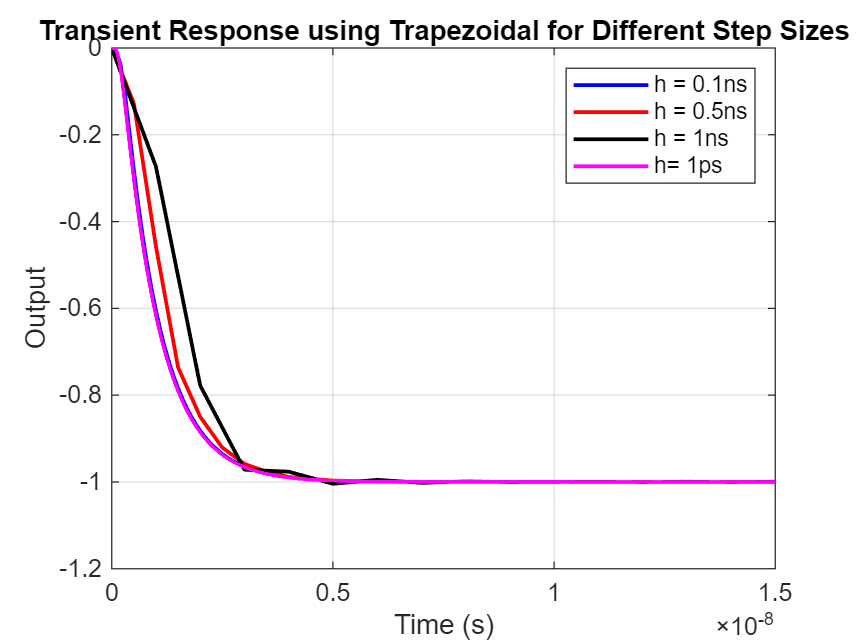


h2 = 0.1e-9;
h3 = 0.5e-9;
h4 = 1e-9;
[tpoints_trap2, r_trap2] = trapezoidal(t1, t2, h2, in, out);
[tpoints_trap3, r_trap3] = trapezoidal(t1, t2, h3, in, out);
[tpoints_trap4, r_trap4] = trapezoidal(t1, t2, h4, in, out);


figure
plot(tpoints_trap2, r_trap2,'b','LineWidth',1.5)
hold on
plot(tpoints_trap3, r_trap3,'r','LineWidth',1.5)
plot(tpoints_trap4, r_trap4,'k','LineWidth',1.5)
plot(tpoints_trap,r_trap, 'm','LineWidth',1.5)
xlabel('Time (s)')
ylabel('Output')
title('Transient Response using Trapezoidal for Different Step Sizes')
legend('h = 0.1ns','h = 0.5ns','h = 1ns', 'h= 1ps')
grid on

Foirward euler

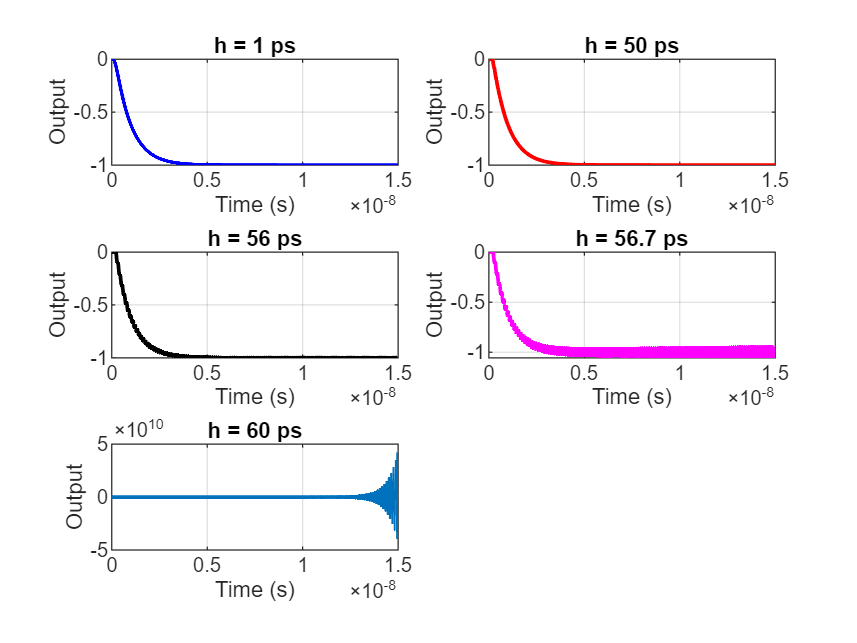

clc
circuit2
G;
C;
b;
t1 = 0;
t2 = 15e-9;
h = 1e-12;
in = 'min(t/(50e-12),1)';
out = 4;
h2 = 50e-12;
h3 = 56e-12;
h4 = 56.70e-12;
h5 = 60e-12;
[t_fwd2,r_fwd2] = feuler(t1, t2, h, in, out);
[t_fwd22,r_fwd22] = feuler(t1, t2, h2, in, out);
[t_fwd23,r_fwd23] = feuler(t1, t2, h3, in, out);
[t_fwd24,r_fwd24] = feuler(t1, t2, h4, in, out);
[t_fwd25,r_fwd25] = feuler(t1, t2, h5, in, out);
figure

subplot(3,2,1)
plot(t_fwd2, r_fwd2,'b','LineWidth',1.5)
title('h = 1 ps')
xlabel('Time (s)')
ylabel('Output')
grid on

subplot(3,2,2)
plot(t_fwd22, r_fwd22,'r','LineWidth',1.5)
title('h = 50 ps')
xlabel('Time (s)')
ylabel('Output')
grid on

subplot(3,2,3)
plot(t_fwd23, r_fwd23,'k','LineWidth',1.5)
title('h = 56 ps')
xlabel('Time (s)')
ylabel('Output')
grid on

subplot(3,2,4)
plot(t_fwd24, r_fwd24,'m','LineWidth',1.5)
title('h = 56.7 ps')
xlabel('Time (s)')
ylabel('Output')
grid on

subplot(3,2,5)
plot(t_fwd25, r_fwd25,'LineWidth',1.5)
title('h = 60 ps')
xlabel('Time (s)')
ylabel('Output')
grid on

Poles Calculation

A = -inv(G)*C

A =   -1.0000e-10  -1.0000e-10  -1.0000e-10  -1.0000e-10
  -1.0000e-10  -2.0000e-10  -2.0000e-10  -2.0000e-10
  -1.0000e-10  -2.0000e-10  -3.0000e-10  -3.0000e-10
  -1.0000e-10  -2.0000e-10  -3.0000e-10  -4.0000e-10


lambda = eig(A)

lambda =   -8.2909e-10
  -1.0000e-10
  -4.2602e-11
  -2.8312e-11



poles = 1./lambda

poles =   -1.2061e+09
  -1.0000e+10
  -2.3473e+10
  -3.5321e+10


h_max = min(2./abs(poles))

h_max =    5.6624e-11


A2 = -inv(C)*G;
lambda2 = eig(A2)

lambda2 =   -3.5321e+10
  -2.3473e+10
  -1.0000e+10
  -1.2061e+09


h_max2 = min(2./abs(lambda2))

h_max2 =    5.6624e-11
